clear all, close all, clc

## Example 4.1

### a) 

First, find the thing

syms N L t
R_t = exp(-L*t);
R_s = 2*R_t^N - R_t^(2*N)

$$R\_s = 2\,{\left({\mathrm{e}}^{-L\,t}\right)}^{N}-{\left({\mathrm{e}}^{-L\,t}\right)}^{2\,N}$$

R_s = simplify(R_s)         % simplify the exprsn

$$R\_s = -{\left({\mathrm{e}}^{-L\,t}\right)}^{N}\,\left({\left({\mathrm{e}}^{-L\,t}\right)}^{N}-2\right)$$

### b)

syms t NL real

Let's find MTTF

R_s = exp(-NL*t) *( 2 - exp(-NL*t));
MTTF = int(R_s,t, 0, inf)

$$MTTF = \frac{3}{2\,\mathrm{NL}}-\frac{\lim_{t\to \infty }{\mathrm{e}}^{-2\,\mathrm{NL}\,t}\,\left(4\,{\mathrm{e}}^{\mathrm{NL}\,t}-1\right)}{2\,\mathrm{NL}}$$

MTTF = limit(MTTF);

## Example 4.2

Given,

R = 0.4;
N = 5;
M = 3;


$$R_{M\left|N\right.} {\left(t\right)}=\sum_{n,M}^N {\left(\begin{array}{c}
N\\
n
\end{array}\right)}{{\left[R{\left(t\right)}\right]}}^n {{\left(1-R{\left(t\right)}\right)}}^{N-n}$$


R_MN = 0;
for n = M:1:N
        C = nchoosek(N,n);
    R_n(n) = C *R^n *(1 - R)^(N-n);
    R_MN = R_MN + R_n(n); 
end 
R_MN

R_MN = 0.3174

## Eqn 23

syms t L1 L2 tu real
R1 = exp(-L1*t);
R2 = exp(-L2*t);
R12 = exp(-L1*tu);      % expressed i.t.o tu
R22 = exp(-L2*(t-tu))

$$R22 = {\mathrm{e}}^{-L_{2}\,\left(t-\mathrm{tu}\right)}$$


$$F_1 \left(\tau \;\right)=1-R_1 \left(\tau \;\right)$$


F12 = 1 - R12;           % failure probab, @ tu
Exp = F12 *R22;
Rs_s = int(Exp, tu, 0, t)

$$Rs\_s = \frac{{\mathrm{e}}^{-L_{1}\,t}-{\mathrm{e}}^{-L_{2}\,t}}{L_{1}-L_{2}}-\frac{{\mathrm{e}}^{-L_{2}\,t}-1}{L_{2}}$$

## Example 4.3

Given,

R_sw = 0.99;    % reliability, switching
R = 0.8;        % reliable, usual
R_s = 0.95;     % ..standby
t = 1;          % active year
t_s = 2;        % standby year

Now, let's find the hazard rate


$$R\left(t\right)=\exp \left(-\lambda t\;\right)$$


lm = -log(R) /t    % hazard rate, operation, y^-1

lm = 0.2231

lm_s = -log(R_s) /t_s % standby

lm_s = 0.0256

Then the system reliability goes  by-


$$R_{sy} {\left(t\right)}=\exp {\left(-\lambda t\right)}{\left\{1+R_{sw} \frac{\lambda }{\lambda^* }{\left[1-\exp {\left(-\lambda^* t\right)}\right]}\right\}}$$


t = 0.5;        % operation time
    C1 = R_sw *lm/lm_s *( 1 - exp(-lm_s*t) );
R_sy = exp(-lm*t)* (1 + C1)

R_sy = 0.9926

## Decomposition, Cross Link

syms t L
R = exp(-L*t);
[R1, R2, R3, R4, R5] = deal(R);         % assigning same value in each variables

Now, let's do the decomposition analysis. Here-

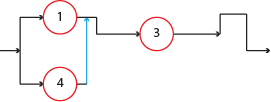

R_sy_k = R3*(1 - (1-R1)*(1-R4) );

And, 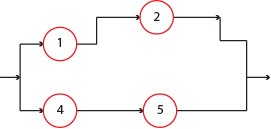

R_sy_kb = (1-R) *(1 - (1 -R1*R2)*(1 -R4*R5) );

$$R\_sy\_kb = \left({\left({\mathrm{e}}^{-2\,L\,t}-1\right)}^{2}-1\right)\,\left({\mathrm{e}}^{-L\,t}-1\right)$$

R_sy_L = R_sy_k + R_sy_kb;
R_sy_L = simplify(R_sy_L)

$$R\_sy\_L = \left({\left({\mathrm{e}}^{-2\,L\,t}-1\right)}^{2}-1\right)\,\left({\mathrm{e}}^{-L\,t}-1\right)-{\mathrm{e}}^{-L\,t}\,\left({\left({\mathrm{e}}^{-L\,t}-1\right)}^{2}-1\right)$$

Now, lets find the MTTF_sy

MTTF_sy = int(R_sy_L, t, 0, inf)

$$MTTF\_sy = \frac{\lim_{t\to \infty }{\mathrm{e}}^{-5\,L\,t}\,\left(5\,{\mathrm{e}}^{L\,t}+20\,{\mathrm{e}}^{2\,L\,t}-40\,{\mathrm{e}}^{3\,L\,t}-4\right)}{20\,L}+\frac{19}{20\,L}$$

###############################

## Functions